clc
clear

## Modern Controller test

load("params.mat", ...
    "sys_ss","inputs","outputs","states", "sigma", 'm_c');

%sys_ss = ss(sys_ss.A, sys_ss.B,[1 0 0 0;0 0 1 0], 0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])


### Cart

syms x              % [m]       position 
syms x_dot_c        % [m/s]     velocity
syms x_ddot_c       % [m/s^2]   acceleration
syms T_c            % [N]       tension force
syms F_c            % [N]       external force

m_c = 0.5           % [Kg]      mass of cart

m_c = 0.5000

b_c = 5             % [N/(m/s)] damping coefficient, cart

b_c = 5

g = 9.82            %           gravity coefficient

g = 9.8200

F_gc = m_c*g        %           gravity for cart

F_gc = 4.9100

F_n = F_gc          %           normal force

F_n = 4.9100

F_dc = b_c*x_dot_c

$$F\_dc = 5\,{\dot{x}}_{c}$$


l_t = 1.78

l_t = 1.7800

### Pendulum

syms theta             % [rad]     angle of pendulum
syms theta_dot         % [rad/sec] angle velocity
syms theta_ddot        % [rad/sec^2] angle acceleration
syms tau_e             % [Nm]      external torque
syms t_p               %           tension of pendulum
syms F_dist            % [N]       disturbance force
syms F_gp              % [N]       gravity of pendulum


m_p = 0.084            % [Kg]      mass of the pendulum

m_p = 0.0840

m_rod = 0.082          % [Kg]      mass of the rod

m_rod = 0.0820

m_wa = 0.002           % [Kg]      mass of the weight attached

m_wa = 0.0020

l_rod = 0.35           % [m]       length of rod

l_rod = 0.3500

l_p = (m_rod*(l_rod/2)+m_wa*l_rod)/(m_rod+m_wa)         % [m] length to center of mass

l_p = 0.1792

b_p = 0.0012                                            % [N/(m/s)] damping coefficient, pendulum

b_p = 0.0012

F_dp = b_p*theta_dot                                    % [N] damping force of pendulum

$$F\_dp = \frac{3\,\dot{\theta }}{2500}$$

h = l_p*cos(theta) 

$$h = \frac{43\,\cos\left(\theta \right)}{240}$$

### Preparing the statespace model

%Ctr = ctrb(sys_ss);
%rank(Ctr)

As the rank of the controllability matrix is full, a controller can be implemented.

firstly the poles of the openloop is found.

pole(sys_ss)

ans =          0
  -11.5752
   -6.3737
    7.4291


%pzmap(sys)

## State feedback control

pole assignment according to Controllable cannonical form, by place in matLab.

% pole_placement = [-sigma*2+1i,-sigma*2-1i,-sigma*3+2i,-sigma*3-2i] % LQR could be used where Q=C'C and values for cost instead of the 1's
% F = -place(sys_ss.A, sys_ss.B, pole_placement)
% 
% A_cl = sys_ss.A+sys_ss.B*F
% 
% % sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])
% sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',outputs)
% step(sys_cl)
% stepinfo(sys_cl,'SettlingTimeThreshold',0.08)


## PI state feedback hvor der kun estimeres på cart position

Making a integral control of the state feedback controller

Ctest = [1 0 0 0]

Ctest =      1     0     0     0


A_e = [sys_ss.A zeros(4,1);
        Ctest zeros(1,1)]

A_e =          0    1.0000         0         0         0
         0  -10.0000    1.6498   -0.0134         0
         0         0         0    1.0000         0
         0  -55.8140   64.0173   -0.5198         0
    1.0000         0         0         0         0


B_e = [sys_ss.B; zeros(1,1)]

B_e =          0
    2.0000
         0
   11.1628
         0


C_e = [Ctest zeros(1,1)]

C_e =      1     0     0     0     0


D_e = 0

D_e = 0


rank(ctrb(A_e, B_e))

ans = 5


poles = [-sigma*2+1i,-sigma*2-1i,-sigma*3+2i,-sigma*3-2i,-sigma*4]

poles =   -4.7539 + 1.0000i  -4.7539 - 1.0000i  -7.1309 + 2.0000i  -7.1309 - 2.0000i  -9.5079 + 0.0000i


Fe = -place(A_e,B_e,poles)

Fe =    87.1466   34.1496  -63.0938   -8.1572  112.2749


F = Fe(:,1:4)

F =    87.1466   34.1496  -63.0938   -8.1572


F_I = Fe(:,5:end)

F_I = 112.2749

poles(1:4)

ans =   -4.7539 + 1.0000i  -4.7539 - 1.0000i  -7.1309 + 2.0000i  -7.1309 - 2.0000i



O = obsv(sys_ss.A, sys_ss.C)

O =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0  -10.0000    1.6498   -0.0134
         0  -55.8140   64.0173   -0.5198
         0  100.7476  -17.3551    1.7907
         0  587.1512 -125.3554   65.0351


rank(O)

ans = 4

L = -place(sys_ss.A', sys_ss.C', poles(1:4)).'

L =    -3.9510    0.0301
   -7.5885   -2.2130
   12.4554   -9.2989
   -8.1094  -90.2762


## pendcontroller

C_angle = [0 0 1 0]

C_angle =      0     0     1     0


sys_pendulum = ss(sys_ss.A,sys_ss.B,C_angle,0)

sys_pendulum =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0      -10     1.65  -0.0134
   x3        0        0        0        1
   x4        0   -55.81    64.02  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



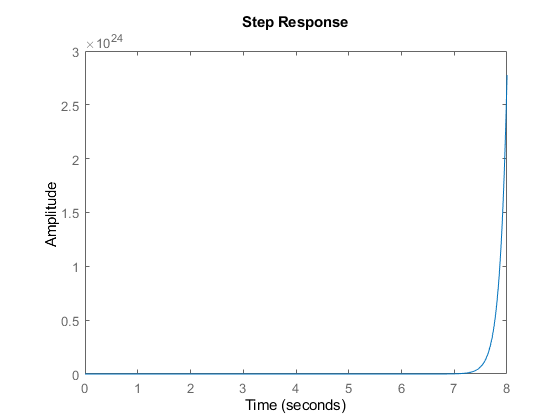

step(sys_pendulum)

PendController = pidtune(sys_pendulum, "PIDF")

PendController =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 363, Ki = 3.62e+03, Kd = 8.93, Tf = 0.000904
 
Continuous-time PIDF controller in parallel form.




sysclosed = feedback(sys_pendulum, PendController)

sysclosed =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2           0         -10  -2.048e+04     -0.0134       -7246  -1.976e+04
   x3           0           0           0           1           0           0
   x4           0      -55.81  -1.143e+05     -0.5198  -4.044e+04  -1.103e+05
   x5           0           0           1           0           0           0
   x6           0           0       -1106           0           0       -1106
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
   x5      0
   x6      0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



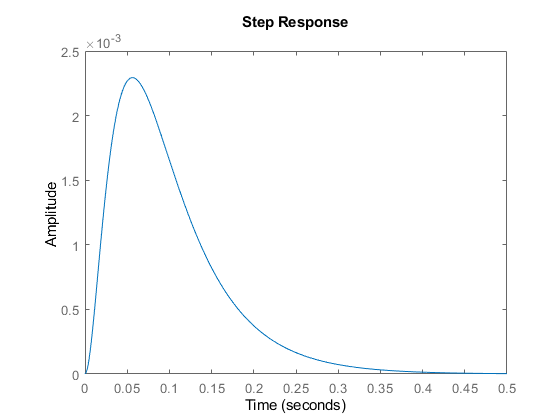

step(sysclosed)

## test 2


$$\left\lbrack \begin{array}{c}
\left(m_c +m_p \right)\cdot \ddot{x_c } -m_p \cdot l_p \cdot \ddot{\;\theta \;} \cdot \cos \left(\theta \;\right)+m_p \cdot l_p \cdot \dot{\;\theta^2 } \cdot \sin \left(\theta \;\right)\\
m_p \cdot l_p^2 \cdot \ddot{\theta} -m_p \cdot l_p \cdot \ddot{x_c } \cdot \cos \left(\theta \right)-m_p \cdot g\cdot l_p \cdot \sin \left(\theta \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_c -b_c \cdot \dot{x_c } \\
-F_{\textrm{dist}} -b_p \cdot \dot{\theta} 
\end{array}\right\rbrack$$


syms ddx_c theta dtheta ddtheta x_c dx_c

eqn1 = (m_c+m_p)*ddx_c -m_p*l_p*ddtheta*cos(theta) +m_p*l_p*dtheta^2*sin(theta) == F_c-b_c*dx_c 

$$eqn1 = \frac{301\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}}{20000}+\frac{73\,{\mathrm{ddx}}_{c}}{125}-\frac{301\,\mathrm{ddtheta}\,\cos\left(\theta \right)}{20000}=F_{c}-5\,{\mathrm{dx}}_{c}$$

eqn2 = m_p*l_p^2*ddtheta -m_p*l_p*ddx_c*cos(theta) -m_p*g*l_p*sin(theta) == -F_dist-b_p*dtheta

$$eqn2 = \frac{6217609597552673\,\mathrm{ddtheta}}{2305843009213693952}-\frac{5324731940229703\,\sin\left(\theta \right)}{36028797018963968}-\frac{301\,{\mathrm{ddx}}_{c}\,\cos\left(\theta \right)}{20000}=-F_{\mathrm{dist}}-\frac{3\,\mathrm{dtheta}}{2500}$$



digits(4);
eqn1 = isolate(eqn1, ddx_c);
vpa(eqn1)

$$ans = {\mathrm{ddx}}_{c}=-0.02577\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+1.712\,F_{c}-8.562\,{\mathrm{dx}}_{c}+0.02577\,\mathrm{ddtheta}\,\cos\left(\theta \right)$$


digits(4);
eqn2 = isolate(eqn2, ddtheta);
vpa(eqn2)

$$ans = \mathrm{ddtheta}=54.81\,\sin\left(\theta \right)-0.445\,\mathrm{dtheta}-370.9\,F_{\mathrm{dist}}+5.581\,{\mathrm{ddx}}_{c}\,\cos\left(\theta \right)$$



eqn2subbed = subs(eqn2, ddx_c, - vpa('0.02577')*sin(theta)*dtheta^2 + vpa('1.712')*F_c - vpa('8.562')*dx_c + vpa('0.02577')*ddtheta*cos(theta));
eqn2subbed = isolate(eqn2subbed, ddtheta)

$$eqn2subbed = \mathrm{ddtheta}=\frac{5.589e+22\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+1.729e+23\,\mathrm{dtheta}+1.441e+26\,F_{\mathrm{dist}}-2.13e+25\,\sin\left(\theta \right)-3.713e+24\,F_{c}\,\cos\left(\theta \right)+1.857e+25\,{\mathrm{dx}}_{c}\,\cos\left(\theta \right)}{5.589e+22\,{\cos\left(\theta \right)}^{2}-3.886e+23}$$



eqn1subbed = subs(eqn1, ddtheta, vpa('54.81')*sin(theta) - vpa('0.445')*dtheta - vpa('370.9')*F_dist + vpa('5.581')*ddx_c*cos(theta));
eqn1subbed = isolate(eqn1subbed, ddx_c)

$$eqn1subbed = {\mathrm{ddx}}_{c}=\frac{1.505e+6\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+6.697e+5\,\cos\left(\theta \right)\,\mathrm{dtheta}-1.0e+8\,F_{c}+5.0e+8\,{\mathrm{dx}}_{c}-8.249e+7\,\cos\left(\theta \right)\,\sin\left(\theta \right)+5.582e+8\,F_{\mathrm{dist}}\,\cos\left(\theta \right)}{8.4e+6\,{\cos\left(\theta \right)}^{2}-5.84e+7}$$





ddtheta == 54.81*sin(theta) - 0.445*dtheta - 370.9*F_dist + 5.581*ddx_c*cos(theta)

$$ans = \mathrm{ddtheta}=\frac{5481\,\sin\left(\theta \right)}{100}-\frac{89\,\mathrm{dtheta}}{200}-\frac{3709\,F_{\mathrm{dist}}}{10}+\frac{5581\,{\mathrm{ddx}}_{c}\,\cos\left(\theta \right)}{1000}$$

ddx_c == (1.505e+6*sin(theta)*dtheta^2 + 6.697e+5*cos(theta)*dtheta - 1.0e+8*F_c + 5.0e+8*dx_c - 8.249e+7*cos(theta)*sin(theta) + 5.582e+8*F_dist*cos(theta))/(8.4e+6*cos(theta)^2 - 5.84e+7)

$$ans = {\mathrm{ddx}}_{c}=\frac{1505000\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+669700\,\cos\left(\theta \right)\,\mathrm{dtheta}-100000000\,F_{c}+500000000\,{\mathrm{dx}}_{c}-82490000\,\cos\left(\theta \right)\,\sin\left(\theta \right)+558200000\,F_{\mathrm{dist}}\,\cos\left(\theta \right)}{8400000\,{\cos\left(\theta \right)}^{2}-58400000}$$

## Matlab easy lqr controller

Q = [ 5   0   0    0; 
      0   1   0    0; 
      0   0  10    0; 
      0   0   0  100];
R = 0.001

R = 1.0000e-03


saturationVal = 1.5;
R = 1/(saturationVal^2)

R = 0.4444


K_lqr = lqr(sys_ss.A, sys_ss.B, Q, R)

K_lqr =    -3.3541  -12.8984   57.1684   16.7280


K_lqr2 = lqr(sys_ss, Q, R)

K_lqr2 =    -3.3541  -12.8984   57.1684   16.7280






Vd = [1   0   0    0; 
      0   1   0    0; 
      0   0   1    0; 
      0   0   0    1] * 1;


Vn = 0.1

Vn = 0.1000



% How to make LQE filter
Kf = -(lqr(sys_ss.A', sys_ss.C', Vd, Vn))'

Kf =    -3.1768   -0.0803
   -0.0491   -1.2372
   -0.0803  -15.3344
   -0.2485 -112.5752


## PI controller test

C = [1 0 0 0];

A_ex = [sys_ss.A zeros(4,1);C zeros(1,1)]

A_ex =          0    1.0000         0         0         0
         0  -10.0000    1.6498   -0.0134         0
         0         0         0    1.0000         0
         0  -55.8140   64.0173   -0.5198         0
    1.0000         0         0         0         0


B_ex = [sys_ss.B; 0]

B_ex =          0
    2.0000
         0
   11.1628
         0


C_ex = [sys_ss.C zeros(2,1)]

C_ex =      1     0     0     0     0
     0     0     1     0     0



sys_ex = ss(A_ex, B_ex, C_ex, 0)

sys_ex =
 
  A = 
            x1       x2       x3       x4       x5
   x1        0        1        0        0        0
   x2        0      -10     1.65  -0.0134        0
   x3        0        0        0        1        0
   x4        0   -55.81    64.02  -0.5198        0
   x5        1        0        0        0        0
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
   x5      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.




co = ctrb(sys_ex)

co = 	1.0e+05 *

         0    0.0000   -0.0002    0.0022   -0.0243
    0.0000   -0.0002    0.0022   -0.0243    0.2775
         0    0.0001   -0.0012    0.0190   -0.2087
    0.0001   -0.0012    0.0190   -0.2087    2.6835
         0         0    0.0000   -0.0002    0.0022


controllability = rank(co)

controllability = 5


% Q = C_ex'*C_ex
% R = 1

P = [-5 -6 -7 -8 -9];


F_e = -place(sys_ex.A, sys_ex.B, P)

F_e =   103.9675   38.6932  -70.4968   -9.1256  137.9328


F = F_e(1:4)

F =   103.9675   38.6932  -70.4968   -9.1256


F_I = F_e(5)

F_I = 137.9328

## discrete LQG

Ts = 1/100;
K_DLQR = -lqrd(sys_ss.A,sys_ss.B,Q,R,Ts)

K_DLQR =     1.7785    9.1981  -33.4501   -9.0232




Kfd = -(lqrd(sys_ss.A', sys_ss.C', Vd, Vn,Ts))'

Kfd =    -0.3196   -0.1636
   -0.0151   -1.2733
   -0.1633  -14.3287
   -1.2074 -106.4373
